clc, clear all

% CREATE TRANSFER FUNCTION
num = [ 0 0.523  -0.39 ];
den = [ 1  -0.595  0.3571 ];
H = tf(num,den,0.1,'Variable','z^-1')

H =
 
     0.523 z^-1 - 0.39 z^-2
  ----------------------------
  1 - 0.595 z^-1 + 0.3571 z^-2
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% SPECIFY INPUT DATA AND TIME VECTOR
u = [  0.2, 2.5, -3.3, -7.2, 2.8, 5.2, -2.4, 4.0, 8.9, 2.0];
t = 0:0.1:0.9;

% SIMULATE RESPONSE OF TRANSFER FUNCTION
y = lsim(H, u, t )

y =                    0
   0.104600000000000
   1.291737000000000
  -1.969669145000000
  -4.111832423975001
   2.529228559414375
   4.600826351453026
  -1.448895839452323
   0.522951885421992
   3.923257076094510


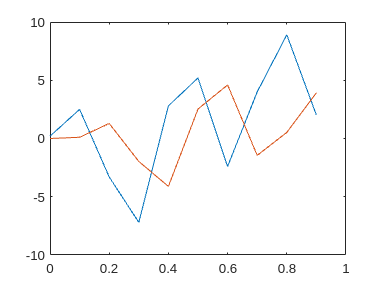


% PLOT RESULTS
figure
plot(t, u)
hold on
plot(t, y)
hold off

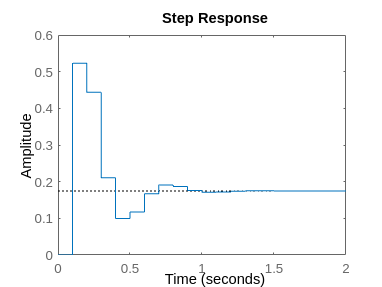


figure
step(H)